# Sasp Project: Dereverb

## Part 1: Reverberation

### RIR generation

Exploit this tool: [https://www.audiolabs-erlangen.de/fau/professor/habets/software/rir-generator](https://www.audiolabs-erlangen.de/fau/professor/habets/software/rir-generator) to generate a simple RIR.

Compile the tools if not already done:

% mex -setup
% mex RIR-Generator-master/rir_generator.cpp

Select parameters for the room (adopted same sintax of site): [https://www.sciencedirect.com/topics/engineering/reverberation-time](https://www.sciencedirect.com/topics/engineering/reverberation-time)

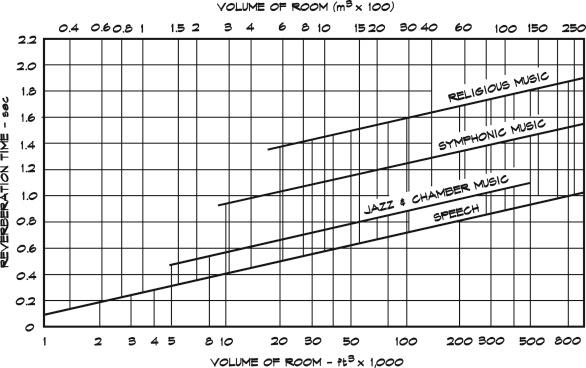

From the image see that values of beta should be chosen between 0.2 for small rooms (3 m per side) and 1.8 for very big rooms (30 m per side);

c = 340;                     % Sound velocity (m/s)
fs = 44100;                  % Sample frequency (samples/s)
r = [2, 1, 1];             % Receiver position [ x y z ] (m)
s = [4, 4, 1];             % Source position [ x y z ] (m)
L = [8, 5, 3];            % Room dimensions [ x y z ] (m)
beta = 0.9;                    % Reverberationtime (s)
% other optional parameters
nsample = fs*beta;              % Number of samples
mtype = 'omnidirectional';     % Type of microphone
order = -1;                  % −1 equals maximum reflection order!
dim = 2;                     % Room dimension
orientation = [0, 0];      % Microphone orientation [azimuth elevation] in radians
hp_filter = 1;               % Enable high-pass filter

Generated RIR (high computation, run only one time):

h = rir_generator(c, fs, r, s, L, beta, nsample, mtype, order, dim, orientation, hp_filter);

Room Impulse Response Generator (Version 2.1.20141124) by Emanuel Habets
Copyright (C) 2003-2014 E.A.P. Habets, The Netherlands.


h = h';

Plot visual representation of the room:

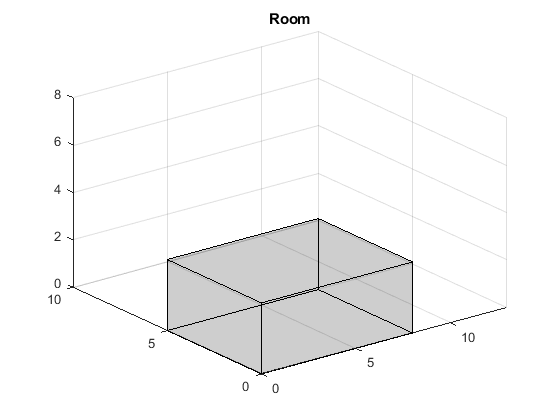

figure(1)
plotcube(L,[0,0,0],0.1,'k')
xlim([0,L(1)+5])
ylim([0,L(2)+5])
zlim([0,L(3)+5])
grid on
title("Room");

Plot generated RIR:

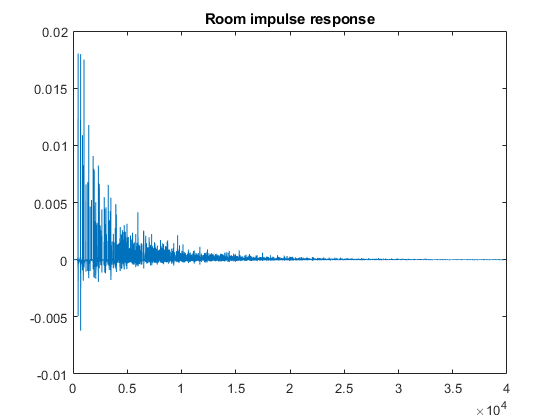

plot(h)
title("Room impulse response")

Import a second RIR:

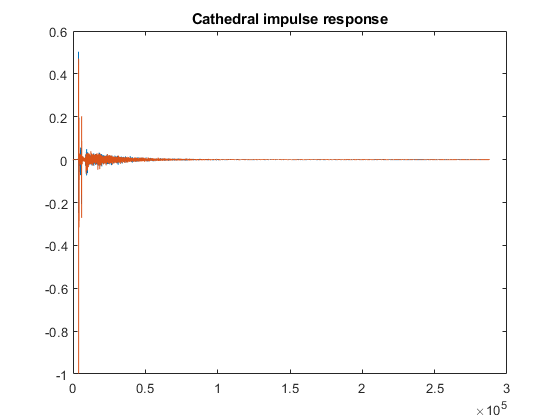

[h1,fs1] = audioread('1st-baptist-nashville/stereo/1st_baptist_nashville_balcony.wav');
plot(h1)
title("Cathedral impulse response")

### Signal generation

Import a simple signal (handclap) to be reverberated and adapt the sampling frequency to match the RIR.

[sig,fs_sig] = audioread('Snap.wav'); 

Adjust the sampling frequency in order to have same $f_s$ of the RIR:

sig = resample(sig,fs,fs_sig);

Plot signals:

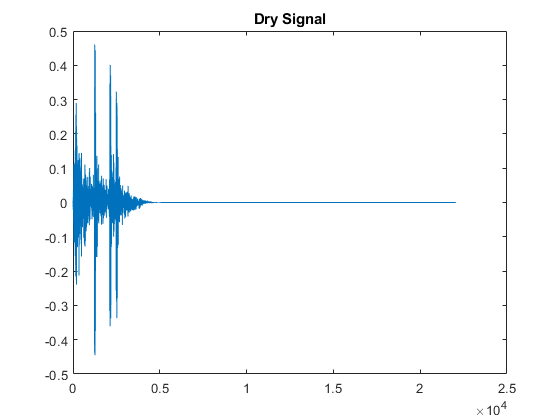

plot(sig)
title("Dry Signal")

### Reverberation of signals

We have 3 alternatives: time convolution, fftfilt (OLA matlab), OLA

#### Signal Convolution

Apply simple convolution in time domain

% rev_sig = conv(sig(:,1), h(:,1));

#### Function fftfilt

Apply OLA algorithm to compute convolution (multiplication in frequency domain)

rev_sig = fftfilt(sig(:,1), h(:,1));

#### OLA algorithm

Apply OLA algorithm as seen at lesson

### Results

Reverberated sound + audio samples

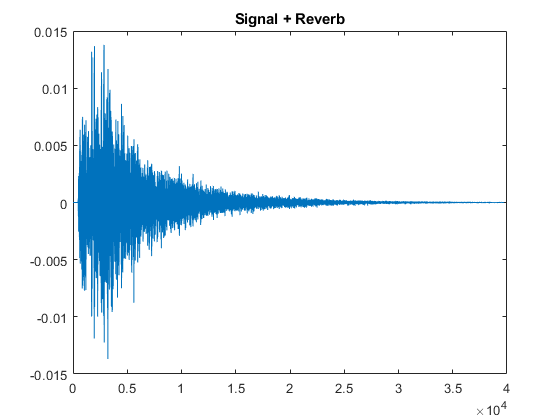

plot(rev_sig)
title("Signal + Reverb")

Dry signal:

soundsc(sig, fs);

Reverberated signal:

soundsc(rev_sig, fs);

## Part 2: Dereverberation